# Adds CV pipe in a network with Bin Function addBinCVPipe.

## This example contains: 

- Load a network. 

- Get from and to nodes for add cv pipe. 

- Plot network. 

- Plot network with changes. 

(Not needed to unload library because not used in this example.)

## Clear - Start Toolkit 

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


## Load a network.

d = epanet('Net1.inp', 'bin');

Load EMT only the bin functions (EMT version {v2.3.03 - Last Update: 02/01/2026}).
Input File Net1.inp loaded successfully.


## Get from and to nodes for add cv pipe.

fromNode = d.getBinNodeNameID.BinNodeNameID{2};
toNode = d.getBinNodeNameID.BinNodeNameID{6};

## Plot network.

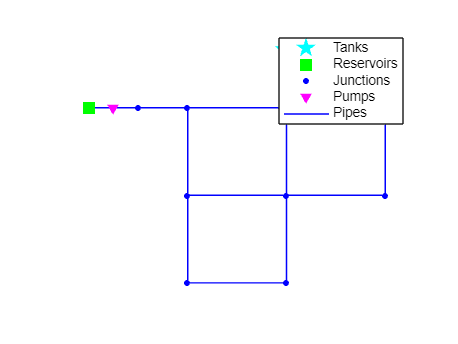

d.Binplot();

errcode = d.addBinCVPipe('CV-P1', fromNode, toNode, 1000, 10, 100);

## Plot network with changes.

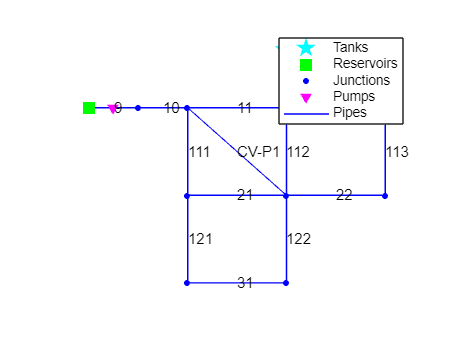

d.Binplot('links','yes');

## Not needed to unload library because not used in this example.